# Sys Course Project

Presentado por:

## Reset Simulation

clc
clearvars
close all
warning('off')

## Data Processing

Explain code here....

### Importing Data

data = importCSV('Colombia_COVID19.csv')

data = 118×7 table
    NUEVOS_CASOS    TOTAL_CASOS    TOTAL_MUERTES    TOTAL_RECUPERADOS    FECHA_ACTUALIZACION    NUEVOS_MUERTOS    NUEVO_RECUPERADOS
    ____________    ___________    _____________    _________________    ___________________    ______________    _________________

          1               1              0                  0                    NaT                  0                   0        
          0               1              0                  0                    NaT                  0                   0        
          0               1              0                  0                    NaT                  0                   0        
          2               3              0                  0                    N

### Data Visualisation

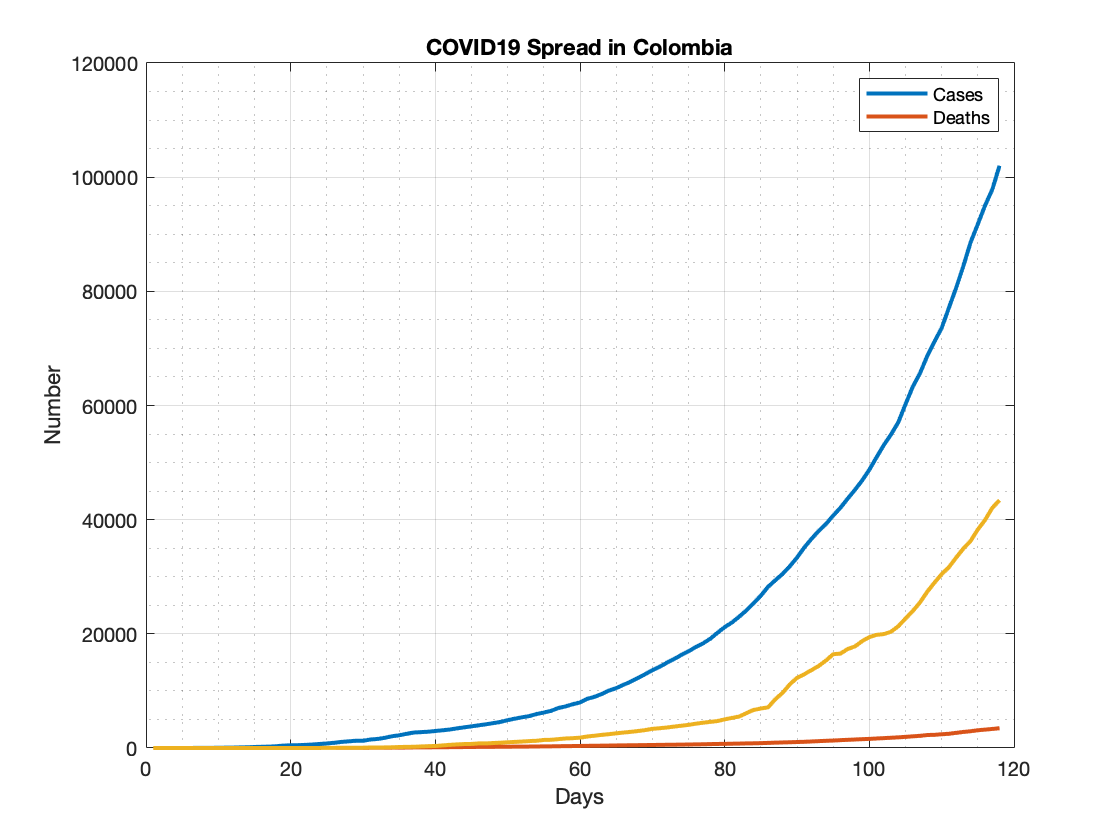

timeElapsed = 1: length(data.NUEVOS_CASOS);

plot(timeElapsed,data.TOTAL_CASOS,timeElapsed,data.TOTAL_MUERTES,timeElapsed, data.TOTAL_RECUPERADOS, 'LineWidth',2)
axis = gca; axis.YRuler.Exponent = 0;
xlabel('Days'), ylabel('Number'), title('COVID19 Spread in Colombia')
legend('Cases','Deaths')
grid on, grid minor

#### Fitting Curve to a Fifth Order Gaussian Model

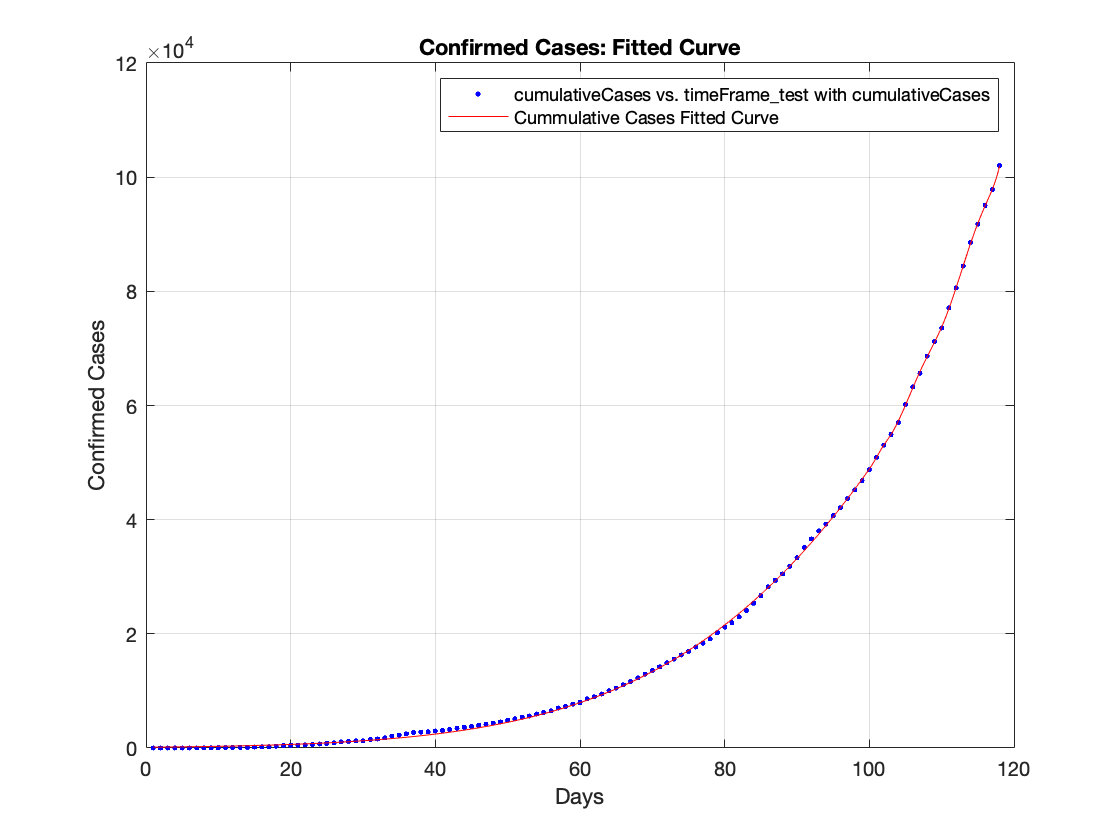

fittedCurve_cases = createFit(timeElapsed, data.TOTAL_CASOS);
xlabel('Days'), ylabel('Confirmed Cases'), title('Confirmed Cases: Fitted Curve')

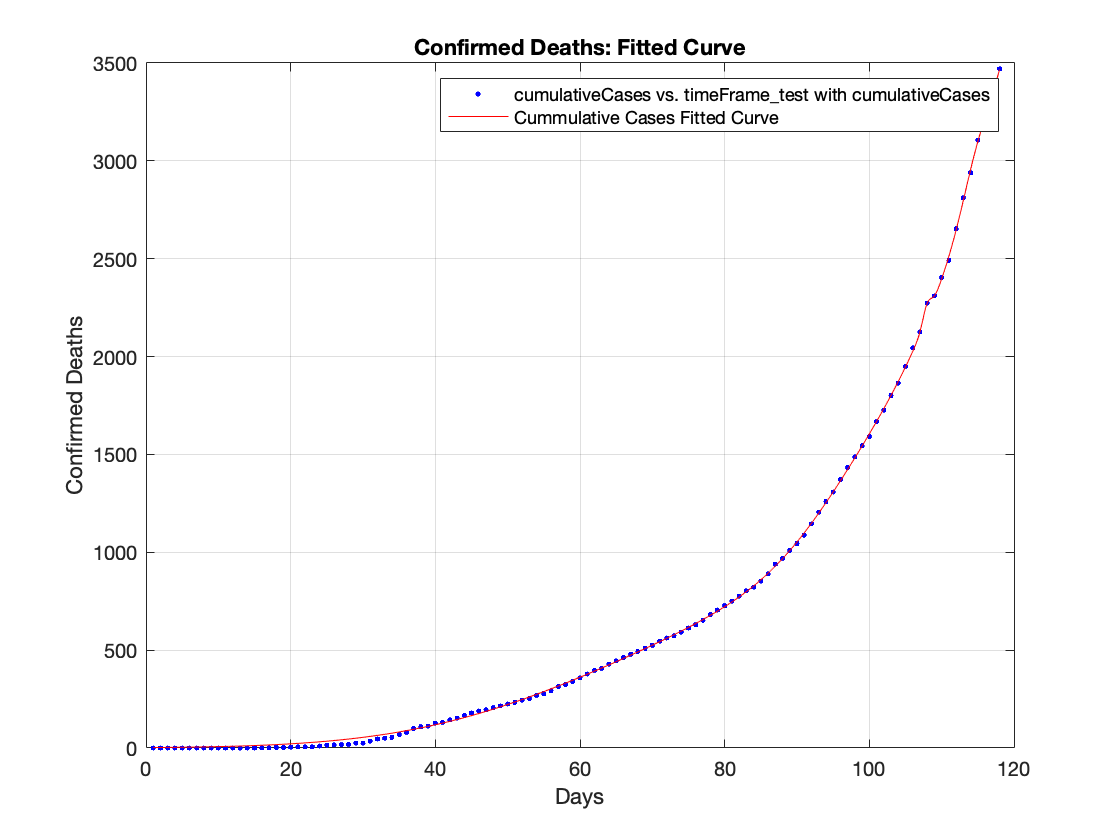

fittedCurve_deaths = createFit(timeElapsed, data.TOTAL_MUERTES);
xlabel('Days'), ylabel('Confirmed Deaths'), title('Confirmed Deaths: Fitted Curve')

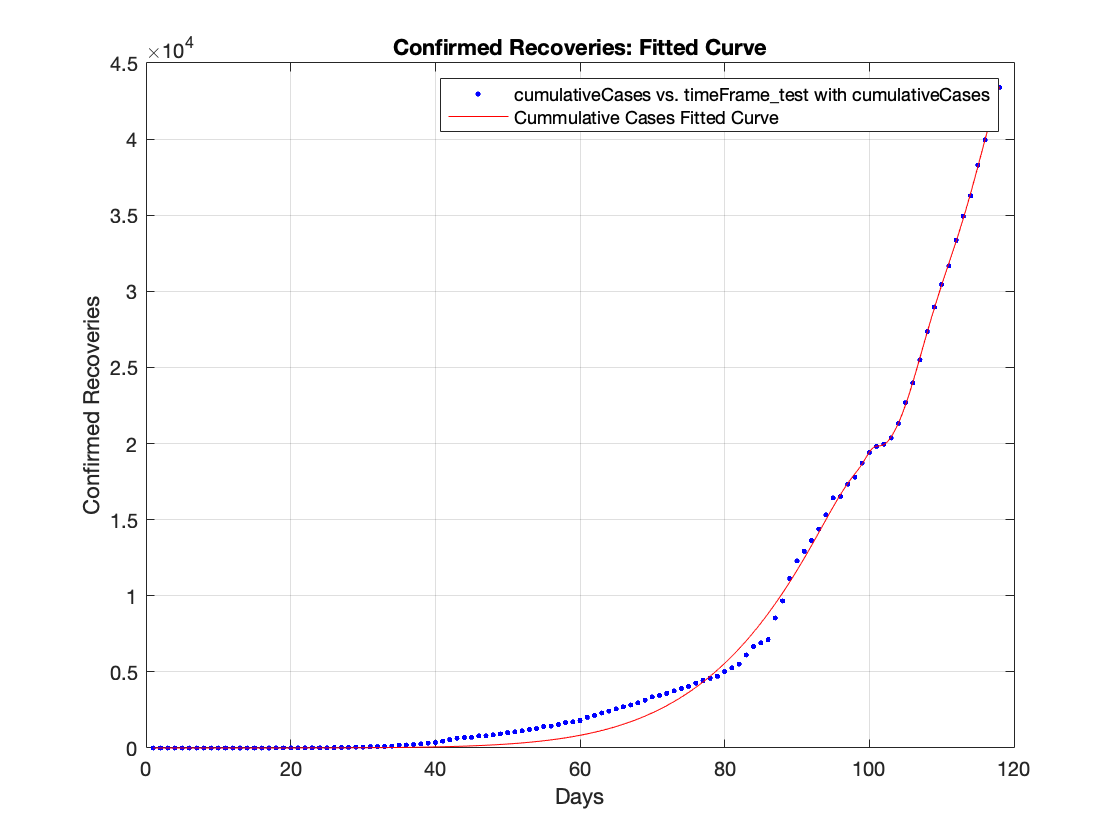

fittedCurve_recoveries = createFit(timeElapsed, data.TOTAL_RECUPERADOS);
xlabel('Days'), ylabel('Confirmed Recoveries'), title('Confirmed Recoveries: Fitted Curve')

## Predicting Cure Stage

vaccineEffectiveness = 0.7;                                     % Number between 0.1 and 1
vaccineCost = 5;                                                % Vaccine cost in USD.
conversionRate = 3758.05;                                       % 1 USD to COP conversion ratio.
availableBudget = 10e9 / conversionRate                         % Available budget (in USD)

availableBudget = 2.6610e+06

availableDoses = floor(availableBudget/vaccineCost)             % Available Doses (Vaccine)

availableDoses = 532190

% PRUEBA COMENTARIO
% Sebastian 33 mil veces 30 hijueputa